% Forest Data Transmission Simulation

% Parameters
num_samples = 1000; % Number of samples
distance = 1000; % Distance between stations in meters
frequency = 2.4e9; % Signal frequency in Hertz (2.4 GHz for WiFi)
tx_power = 30; % Transmit power in dBm
minReceived=-80;

packLost=0;
% Path loss calculation

% Generate random distances in the forest
distances = randi([50, 1000], 1, num_samples);

% Simulate data transmission for each distance
received_power = zeros(1, num_samples);
for i = 1:num_samples
    d = distances(i);
    
    [done, received_power(i)]=SendSignal(2.5,d,tx_power);
    if done==false
        packLost=packLost+1;
    end
end

% Plot results
disp(packLost)

   397



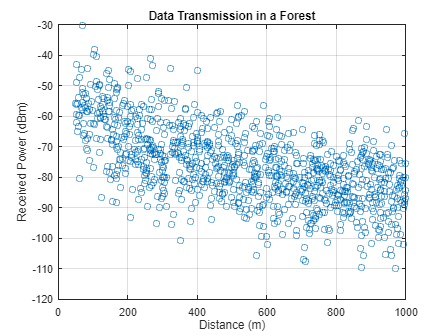

figure;
plot(distances, received_power, 'o');
xlabel('Distance (m)');
ylabel('Received Power (dBm)');
title('Data Transmission in a Forest');
grid on;